# Examples of the different control policies

We run the same examples for the different control policies

- `CCDischarge`

- `CCCharge`

- `CCCV`

## Setup json input

We load some parameter sets for the material property and geometry

jsonfilename = fullfile('ParameterData', 'BatteryCellParameters', 'LithiumIonBatteryCell', ...
                        'lithium_ion_battery_nmc_graphite.json');

jsonstruct_material = parseBattmoJson(jsonfilename);

jsonfilename = fullfile('Examples', 'JsonDataFiles', 'geometry1d.json');
jsonstruct_geometry = parseBattmoJson(jsonfilename);

We merge the material and geometrical parameters in `jsonstruct`

jsonstruct = mergeJsonStructs({jsonstruct_geometry , ...
                               jsonstruct_material
                              });

## Setup Constant Current Discharge control and run simulation

jsonstruct.Control = struct('controlPolicy'     , 'CCDischarge', ...
                            'rampupTime'        , 0.1          , ...
                            'DRate'             , 1            , ...
                            'lowerCutoffVoltage', 2.4);

output = runBatteryJson(jsonstruct);

Solving timestep 001/100:                                            -> 50 Seconds, 399 Milliseconds
| It # | ctrl_EIequation (cell) | ctrl_controlEquation (cell) | ne_co_am_sd_massCons (cell) | ne_co_am_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) | thermal_energyCons (cell) |

We plot the results

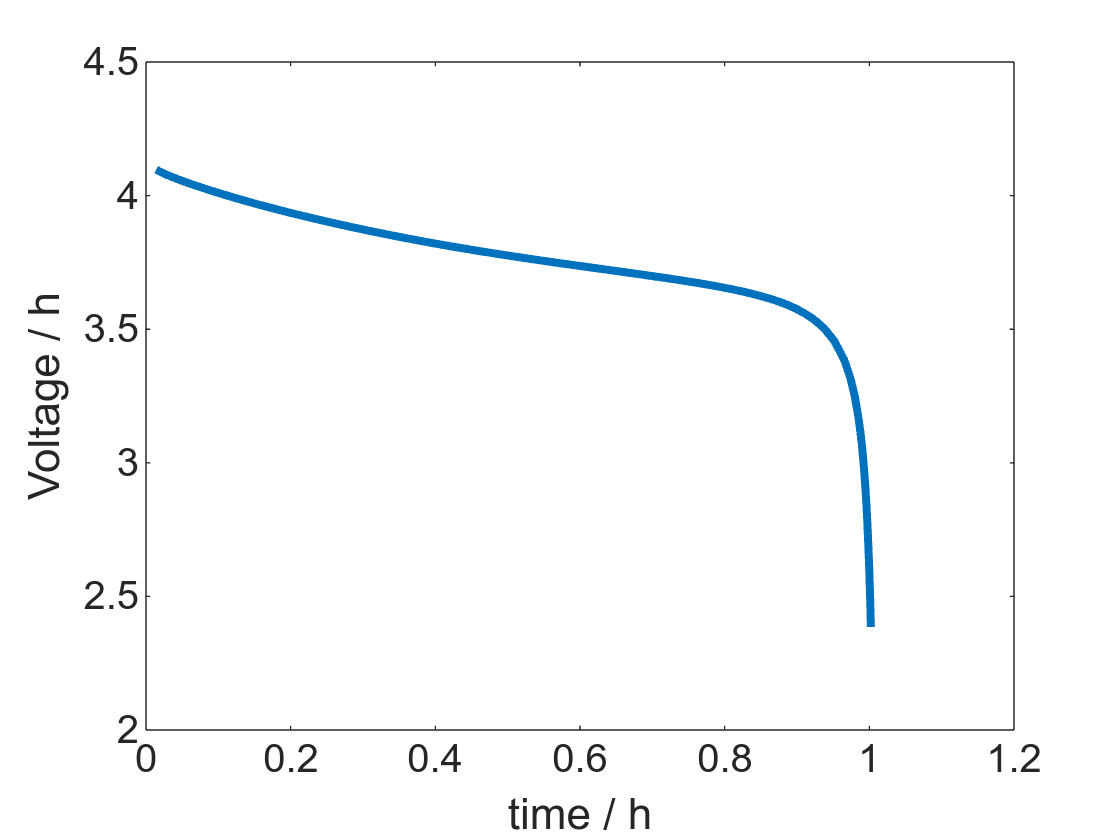

set(0, 'defaulttextfontsize', 15);
set(0, 'defaultaxesfontsize', 15);
set(0, 'defaultlinelinewidth', 3);

figure
states = output.states;
time = cellfun(@(state) state.time, states);
E    = cellfun(@(state) state.Control.E, states);
plot(time/hour, E);
xlabel('time / h');
ylabel('Voltage / h');

## Setup Constant Current Charge control and run simulation

jsonstruct.Control = struct('controlPolicy'     , 'CCCharge', ...
                            'rampupTime'        , 0.1       , ...
                            'CRate'             , 1         , ...
                            'upperCutoffVoltage', 4.1);

We change the state of charge (from 0.99 to 0.01)

jsonstruct.SOC = 0.01;

By default the simulation time is set to 1.4/(DRate) hour. We can change that

jsonstruct.TimeStepping.totalTime = 2*hour;

We run the simulation

output = runBatteryJson(jsonstruct);

Solving timestep 001/100:         -> 72 Seconds
| It # | ctrl_EIequation (cell) | ctrl_controlEquation (cell) | ne_co_am_sd_massCons (cell) | ne_co_am_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) | thermal_energyCons (cell) |

## Plot Results

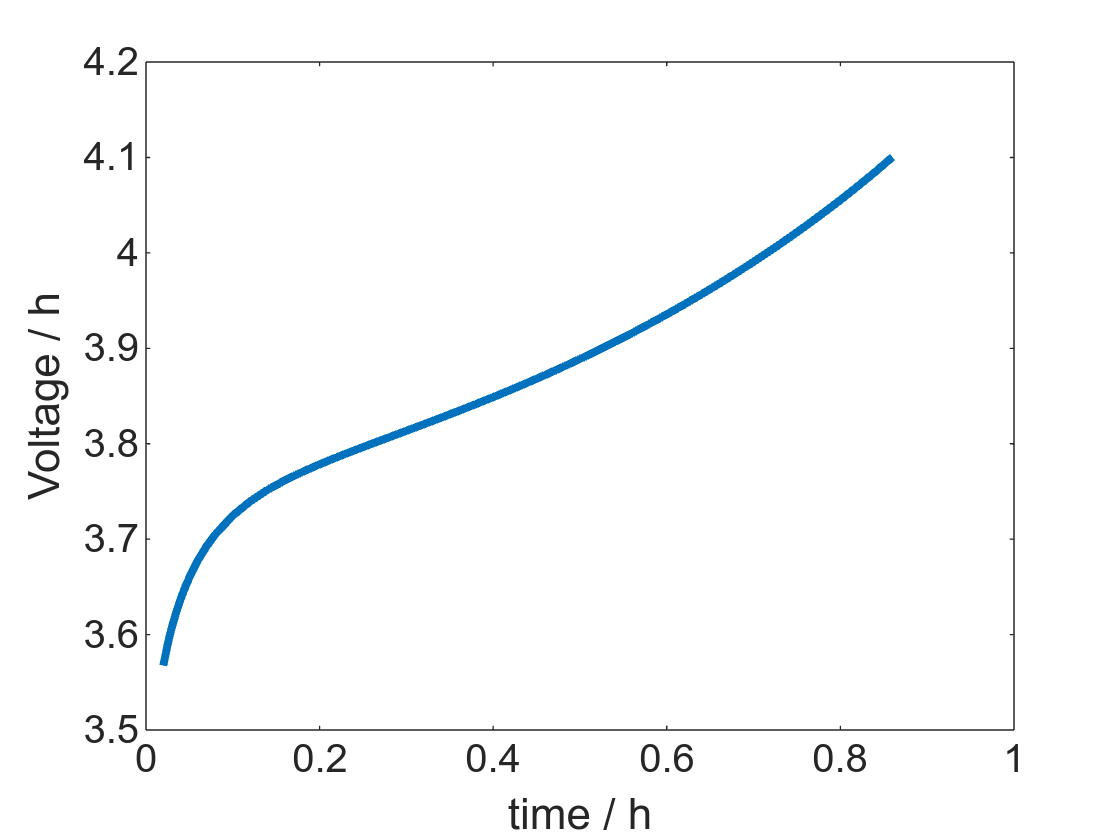

set(0, 'defaulttextfontsize', 15);
set(0, 'defaultaxesfontsize', 15);
set(0, 'defaultlinelinewidth', 3);
figure
states = output.states;
time = cellfun(@(state) state.time, states);
E    = cellfun(@(state) state.Control.E, states);
plot(time/hour, E);
xlabel('time / h');
ylabel('Voltage / h');

## Setup Constant Current Constant Voltage control and run the simulation

jsonstruct.SOC = 0.99;
jsonstruct.Control = struct('controlPolicy'     , 'CCCV'       , ...
                            'initialControl'    , 'discharging', ...
                            'numberOfCycles'    , 2            , ...
                            'CRate'             , 1.5          , ...
                            'DRate'             , 1            , ...
                            'lowerCutoffVoltage', 2.4          , ...
                            'upperCutoffVoltage', 4            , ...
                            'dIdtLimit'         , 2e-6         , ...
                            'dEdtLimit'         , 2e-6);

We run the simulation

output = runBatteryJson(jsonstruct);

Solving timestep 001/100:         -> 144 Seconds
| It # | ctrl_EIequation (cell) | ctrl_controlEquation (cell) | ne_co_am_sd_massCons (cell) | ne_co_am_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) | thermal_energyCons (cell) |

|    3 |*2.39e-13               |*0.00e+00                    | 9.63e-01                    | 9.63e-01                            | 7.68e-01                | 3.77e+35                    | 3.77e+35                            | 2.70e+35                | 3.39e+35                | 3.39e+35              | 1.14e+33                  |
|    4 | 4.52e-03               |*0.00e+00                    | NaN                         | NaN                                 | NaN                     | NaN                         | NaN                                 | NaN                     | NaN                     | NaN                   | NaN                       |
Solver failure after 3 iterations for timestep of length 144 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

|    3 |*2.39e-13               |*0.00e+00                    | 3.79e-01                    | 3.79e-01                            | 3.03e-01                | 1.93e+16                    | 1.93e+16                            | 1.38e+16                | 1.74e+16                | 1.74e+16              | 2.73e+13                  |
|    4 |*2.39e-13               |*0.00e+00                    | NaN                         | NaN                                 | NaN                     | 6.20e+15                    | 6.20e+15                            | 4.43e+15                | NaN                     | NaN                   | NaN                       |
Solver failure after 3 iterations for timestep of length 72 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

|    3 |*2.05e-12               |*0.00e+00                    | 9.56e-01                    | 9.56e-01                            | 7.63e-01                | 3.99e+34                    | 3.99e+34                            | 2.85e+34                | 3.59e+34                | 3.59e+34              | 1.18e+32                  |
|    4 | 4.52e-03               |*0.00e+00                    | NaN                         | NaN                                 | NaN                     | 1.06e+34                    | 1.06e+34                            | 7.57e+33                | NaN                     | NaN                   | NaN                       |
Solver failure after 3 iterations for timestep of length 144 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

|    3 |*2.39e-13               |*0.00e+00                    | 3.77e-01                    | 3.77e-01                            | 3.00e-01                | 6.50e+15                    | 6.50e+15                            | 4.65e+15                | 5.84e+15                | 5.84e+15              | 8.93e+12                  |


|    4 |*2.39e-13               |*0.00e+00                    | 2.17e-02                    | 1.55e-02                            | 3.05e-02                | 2.50e+15                    | 2.50e+15                            | 1.78e+15                | 2.24e+15                | 2.24e+15              | 3.43e+12                  |


|    5 |*2.39e-13               |*0.00e+00                    | 1.48e-01                    | 1.61e-01                            | 8.89e-02                | 1.02e+15                    | 1.02e+15                            | 7.31e+14                | 9.19e+14                | 9.19e+14              | 1.41e+12                  |


|    6 |*2.39e-13               |*0.00e+00                    | 2.08e-02                    | 1.65e-02                            | 2.58e-02                | 4.33e+14                    | 4.33e+14                            | 3.09e+14                | 3.89e+14                | 3.89e+14              | 5.99e+11                  |


|    7 |*2.39e-13               |*0.00e+00                    | 5.08e-03                    | 6.95e-03                            | 1.49e-03                | 1.64e+14                    | 1.64e+14                            | 1.17e+14                | 1.48e+14                | 1.48e+14              | 2.27e+11                  |


|    8 |*2.39e-13               |*0.00e+00                    | 3.82e-04                    | 3.60e-04                            | 1.17e-03                | 6.21e+13                    | 6.21e+13                            | 4.44e+13                | 5.59e+13                | 5.59e+13              | 8.60e+10                  |


|    9 |*2.39e-13               |*0.00e+00                    | 1.39e-03                    | 2.52e-03                            | 1.25e-03                | 2.36e+13                    | 2.36e+13                            | 1.69e+13                | 2.12e+13                | 2.12e+13              | 3.27e+10                  |


|   10 |*2.39e-13               |*0.00e+00                    | 1.76e-03                    | 2.89e-03                            | 9.59e-04                | 8.98e+12                    | 8.98e+12                            | 6.42e+12                | 8.07e+12                | 8.07e+12              | 1.24e+10                  |
|   11 |*2.39e-13               |*0.00e+00                    | 1.18e-03                    | 2.13e-03                            | 1.06e-03                | 3.42e+12                    | 3.42e+12                            | 2.44e+12                | 3.07e+12                | 3.07e+12              | 4.73e+09                  |
Solver did not converge in 10 iterations for timestep of length 72 Seconds. Cutting timestep.

## Plot Results

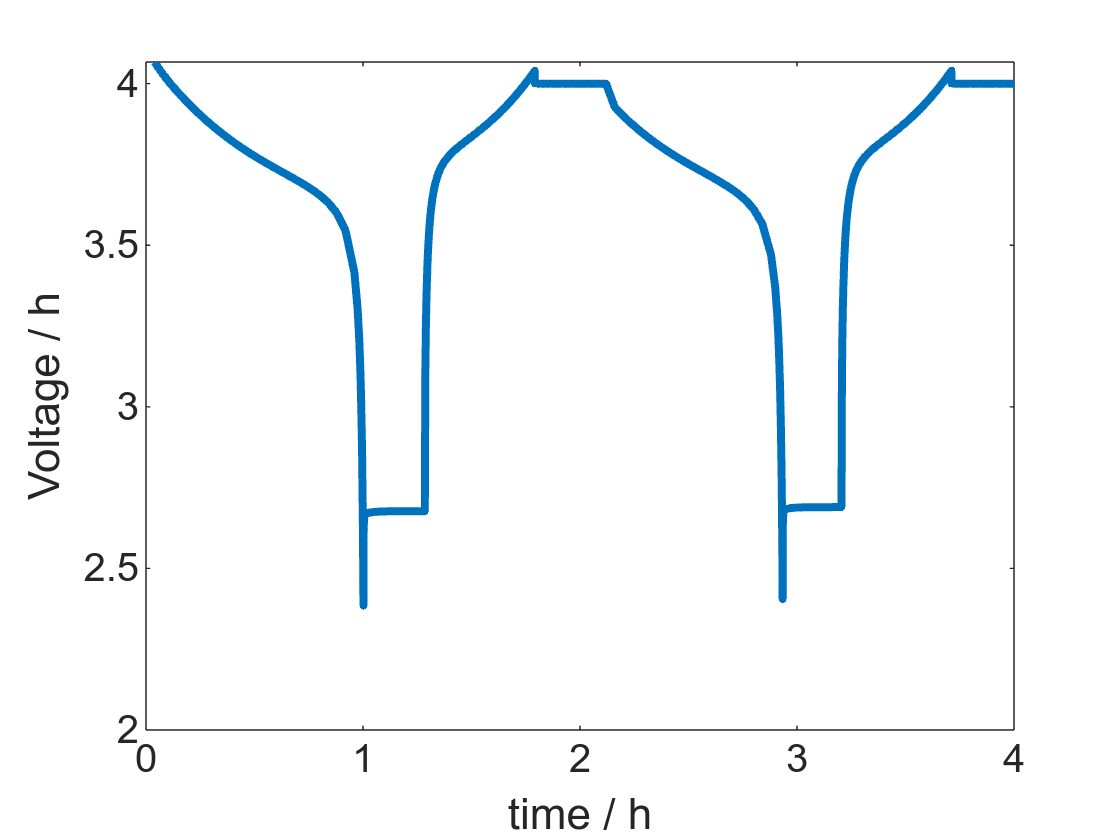

set(0, 'defaulttextfontsize', 15);
set(0, 'defaultaxesfontsize', 15);
set(0, 'defaultlinelinewidth', 3);
figure
states = output.states;
time = cellfun(@(state) state.time, states);
E    = cellfun(@(state) state.Control.E, states);
plot(time/hour, E);
xlabel('time / h');
ylabel('Voltage / h');